direction_names = ["FF","BF","FB","BB"];

s = sysf_two_link_lowRe;

shape_step = 0.05;
% shape is alpha; shapechange is alpha dot
a = s.grid_range(1):shape_step:s.grid_range(2);
adot = -0.5:0.01:0.5;

agree = cell(length(s.geometry.linklengths), 4);

% store velocities at each link and at the body origin
% (link1;link2, x;y;t, a, adot, directions)
link_velocities = zeros(2, 3, length(a), length(adot), 4);
% (x;y;t, a, adot, directions)
body_velocities = zeros(3, length(a), length(adot), 4);

for dir = 0:3
    backwards = [mod(dir,2), floor(dir/2)]; % this is a hacky way to do all 4 direction combos with binary
    friction_direction = [1, 1] - 2 * backwards;
    
    % storage of results for each link
    %agree = cell(size(s.geometry.linklengths));
    % how do I do this without hardcoding?
    agree{1, dir + 1} = zeros(length(a), length(adot));
    agree{2, dir + 1} = zeros(length(a), length(adot));
    for i = 1:length(a)
        shape = a(i);
        
        % these two don't depend on alpha dot:
        % get A(alpha)
        [A, ~, ~, ~, ~] = LowRE_connection_discrete(s.geometry, s.physics, shape, backwards);
        % get Jfull(alpha)
        [~, ~, J_full, ~, ~] = N_link_chain(s.geometry, shape);
        
        for j = 1:length(adot)
            shapechange = adot(j);
            
            % gcirc right
            body_vel = A * shapechange;
            body_velocities(:,i,j,dir+1) = body_vel;
%             velocities(:,3,i,j,dir+1) = body_vel;
    
            for link = 1:length(s.geometry.linklengths)
                % TODO: bug
                link_body_vel = J_full{link} * [body_vel; shapechange];
                link_velocities(link,:,i,j,dir+1) = link_body_vel;
%                 velocities(:,link,i,j,dir+1) = link_body_vel;
                dx_direction = sign(link_body_vel(1)); %index 1 is x, right?
                if(dx_direction == 0) % non-if way to do this?
                    agreement = 1;
                else
                    agreement = friction_direction(link) * dx_direction;
                end
                agree{link, dir + 1}(i,j) = agreement;
            end
        end
    end
end

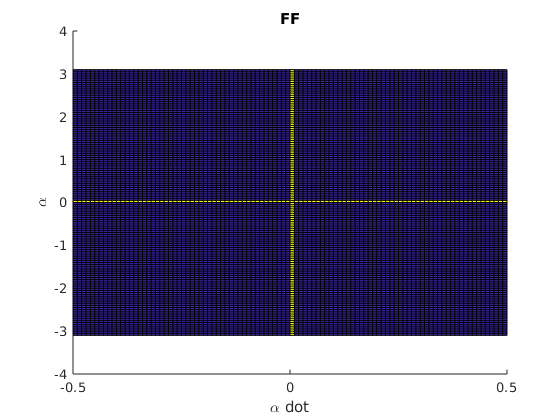

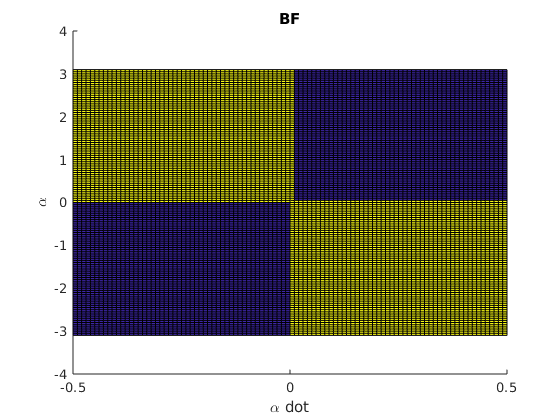

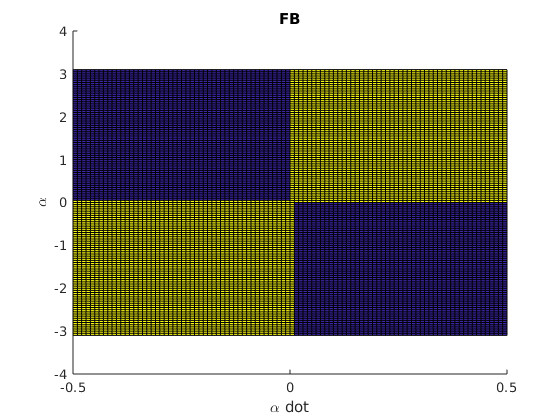

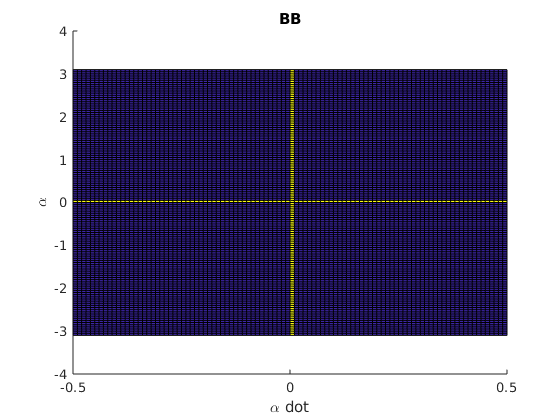

for dir = 0:3
    figure(dir+1);
    clf(dir+1);
    title(direction_names(dir+1));
    xlabel("\alpha dot");
    ylabel("\alpha");
    % summary: link 1 is the 1's digit in binary. link 2 is the 2's digit.
    % so 00 would be agreeing with neither, 10 (= 2) would be agreeing with
    % just link 2, 01 (= 1) would be agreeing with just link 1, and 11 (= 3)
    % would be agreeing with both
    %summary = (agree{1, dir + 1} + 1)/2 + (agree{2, dir + 1} + 1);
    summary = (agree{1, dir + 1} + 1) & (agree{2, dir + 1} + 1);
    surface(adot, a, summary);
end

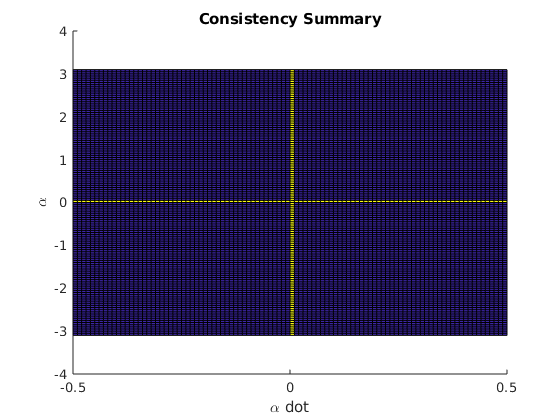


% keep track of any places where there's no solution, one, or multiple
figure(5);
clf(5);
title("Consistency Summary");
xlabel("\alpha dot");
ylabel("\alpha");
direction_summary = zeros(size(agree{1, 1}));
for dir = 0:3
    direction_summary = direction_summary + ((agree{1, dir + 1} + 1) & (agree{2, dir + 1} + 1));
end
surface(adot, a, direction_summary);

% dir = 0; FF = (agree{1, dir + 1} + 1)/2 + (agree{2, dir + 1} + 1);
% dir = 1; BF = (agree{1, dir + 1} + 1)/2 + (agree{2, dir + 1} + 1);
% dir = 2; FB = (agree{1, dir + 1} + 1)/2 + (agree{2, dir + 1} + 1);
% dir = 3; BB = (agree{1, dir + 1} + 1)/2 + (agree{2, dir + 1} + 1);

dir = 0; FF = (agree{1, dir + 1} + 1) & (agree{2, dir + 1} + 1);
dir = 1; BF = (agree{1, dir + 1} + 1) & (agree{2, dir + 1} + 1);
dir = 2; FB = (agree{1, dir + 1} + 1) & (agree{2, dir + 1} + 1);
dir = 3; BB = (agree{1, dir + 1} + 1) & (agree{2, dir + 1} + 1);

% each matrix is pi rotationally symmetric
all(rot90(FF,2) == FF, 'all')

ans = logical
   1


all(rot90(BF,2) == BF, 'all')

ans = logical
   1


all(rot90(FB,2) == FB, 'all')

ans = logical
   1


all(rot90(BB,2) == BB, 'all')

ans = logical
   1


% each matrix is adot-translationally symmetric
% (on each side of axis)
find(any(FF(:,1:size(FF,2)-1) - FF(:,2:size(FF,2)))) == [50 51] %#ok<*EQEFF> 

ans = 1×2 logical array
   1   1


find(any(BF(:,1:size(BF,2)-1) - BF(:,2:size(BF,2)))) == [50 51]

ans = 1×2 logical array
   1   1


find(any(FB(:,1:size(FB,2)-1) - FB(:,2:size(FB,2)))) == [50 51]

ans = 1×2 logical array
   1   1


find(any(BB(:,1:size(BB,2)-1) - BB(:,2:size(BB,2)))) == [50 51]

ans = 1×2 logical array
   1   1



% but not alpha symmetric, of course
find(any(FF(1:size(FF,1)-1,:) - FF(2:size(FF,1),:)))

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


% so we can just take a strip of each matrix at alpha = 1 (or whatever)
% and use it to know the entire rest of the matrix
FFs = FF(:,55);
BFs = BF(:,55);
FBs = FB(:,55);
BBs = BB(:,55);
DSs = direction_summary(:,55);

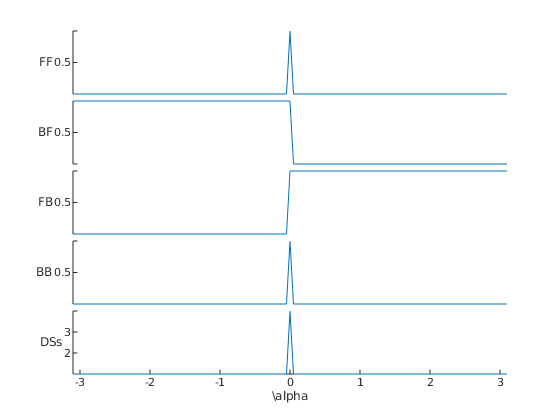

figure()
clf
newYlabels = {'FF','BF','FB','BB', 'DSs'};
stackedplot(a,[FFs BFs FBs BBs DSs], 'DisplayLabels',newYlabels);
xlabel('\alpha');

% There is a mirror symmetry accross the alpha=0 line.
% The consistency values are notted for each link,
% so a point at a=-1 that's consistent in both links would be
% inconsistent in both links at a=1.
A = FFs;
n = ceil(length(A)/2); % index of alpha = 0
notA = ~(mod(A,2)) + ~(floor(A/2))*2;
all(rot90(A(1:n-1), 2) == notA(n+1:length(A)))

ans = logical
   0


A = BFs;
notA = ~(mod(A,2)) + ~(floor(A/2))*2;
all(rot90(A(1:n-1), 2) == notA(n+1:length(A)))

ans = logical
   0


A = FBs;
notA = ~(mod(A,2)) + ~(floor(A/2))*2;
all(rot90(A(1:n-1), 2) == notA(n+1:length(A)))

ans = logical
   0


A = BBs;
notA = ~(mod(A,2)) + ~(floor(A/2))*2;
all(rot90(A(1:n-1), 2) == notA(n+1:length(A)))

ans = logical
   0


% mod(FFs,2); % originally 1's component
% floor(FFs/2); % originally 2's component
% not 0 is 3 (00; 11)
% not 1 is 2 (01; 10)
% ~(mod(FFs,2)) + ~(floor(FFs/2))*2; % negate each and rebuild

% See where changes occur.
a(FFs(1:length(FFs)-1) - FFs(2:length(FFs))~=0)
a(BBs(1:length(BBs)-1) - BBs(2:length(BBs))~=0)
a(BFs(1:length(BFs)-1) - BFs(2:length(BFs))~=0)
a(FBs(1:length(FBs)-1) - FBs(2:length(FBs))~=0)
a(DSs(1:length(DSs)-1) - DSs(2:length(DSs))~=0)

% FF and BB change at the same spot,
% but BF and FB don't line up as nicely.

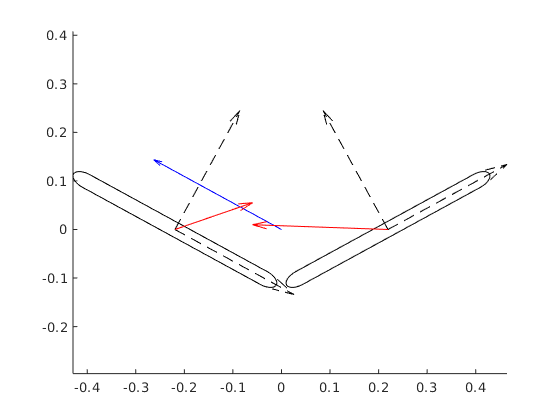

% looking at velocities at certain areas
a_loc = 1;
adot_loc = adot(61); % slightly off from 0.1!! so no exact match!!
dir = 3; % FF BF FB BB
lvel = link_velocities(:,:,a==a_loc,adot==adot_loc,dir);
bvel = body_velocities(:,a==a_loc,adot==adot_loc,dir);
% TODO: improve how the above selection works.
% Use closest-to instead of requiring a value exactly on the linspace.

force_diagram(s, lvel, bvel, a_loc, true);

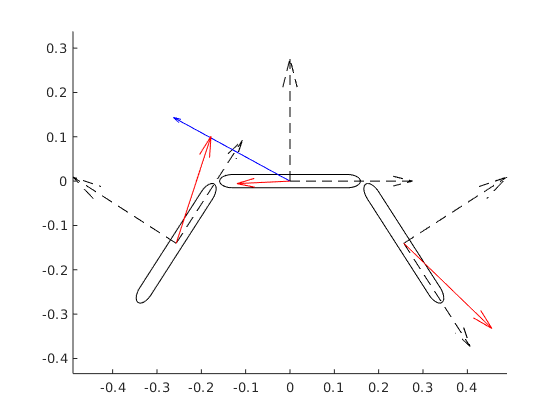

% testing my force diagram tool on a three-link snake!!!
% with dummy velocities
s3 = sysf_three_link_lowRe;
lvel3 = random('Normal', 0, 1, 3, 3);
force_diagram(s3, lvel3, bvel, [-1 -1], true);

% now, what about generating a "blur"?
% transform the points in B from the fat chain
% according to a small step in the direction of the body velocity
% and draw them underneath in grey
% first try one, then try multiple small steps

% will the links also need to be transformed and additional amount?
% I can first just do body velocity as proof-of-code

%this won't be as helpful in animation, but could be great in still
% figures!

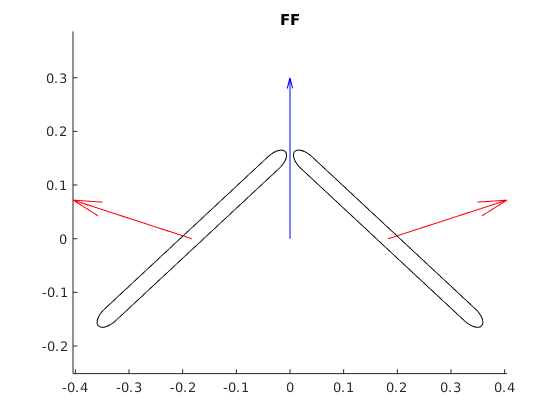

bvel =    -0.0000
    0.0028
    0.0000


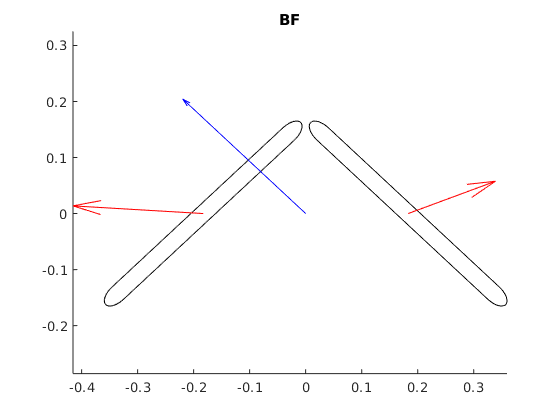

bvel =    -0.0017
    0.0016
    0.0053


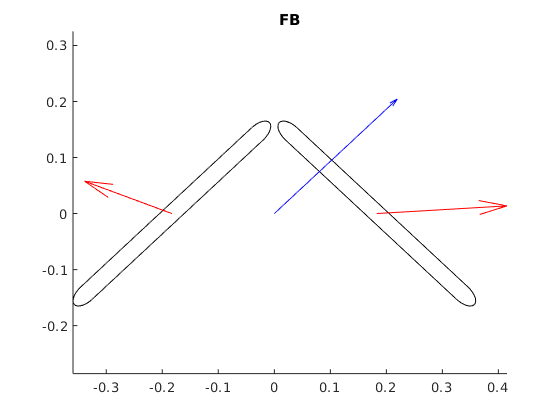

bvel =     0.0017
    0.0016
   -0.0053


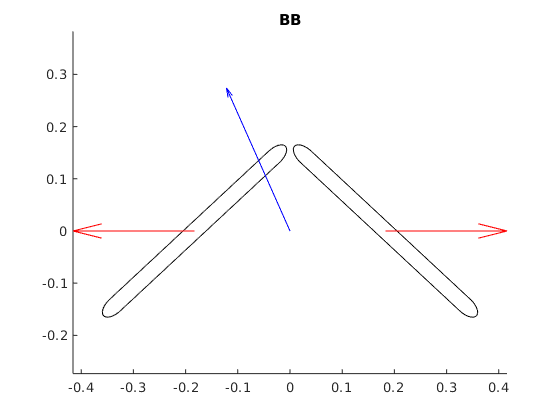

bvel = 	1.0e+-17 *

   -0.1388
    0.3123
    0.1598


% first, improve a and adot selection
alpha = -1.5;
alphadot = 0.1;
for dir=1:4
    [lvel, bvel, a_i, adot_i] = get_velocities(alpha, alphadot, dir, ...
                                        a, adot, link_velocities, body_velocities);
    force_diagram(s, lvel, bvel, a(a_i), false);
    title(newYlabels{dir})
    bvel
    %xlabel(strcat('\alpha = ', string(alpha), ' adot = ', string(adot)))
end

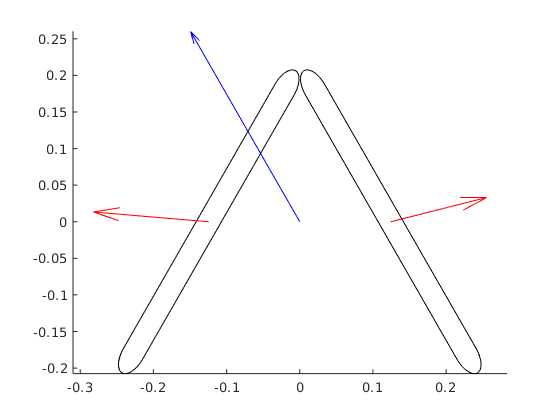

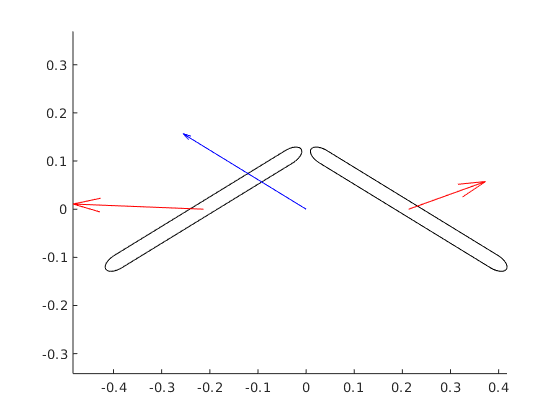

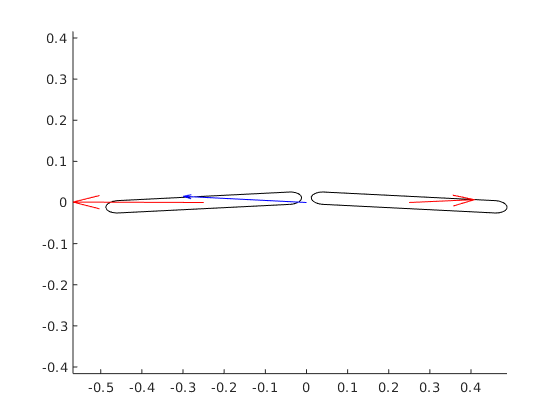

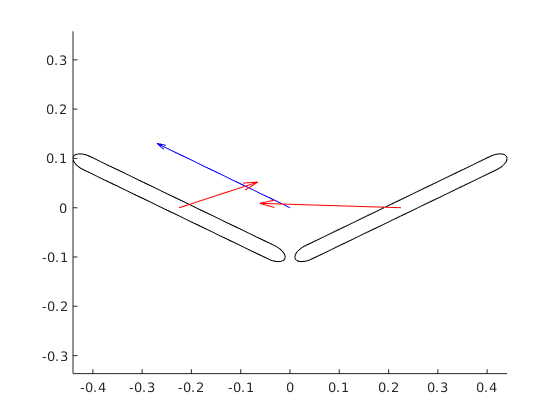

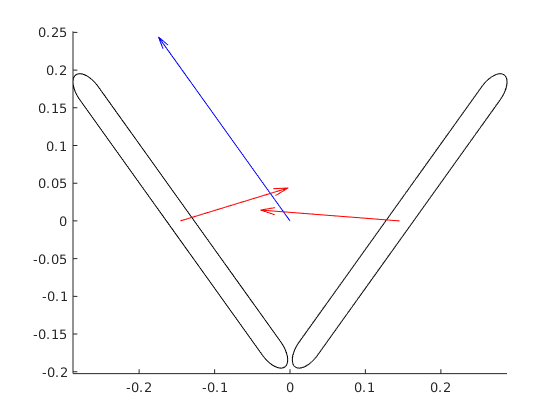

alphadot = 0.1;
for alpha = -2.1:1:1.9
    % we can automatically pick the correct direction
    % FF BF FB BB
    [lvel, bvel, a_i, adot_i] = get_velocities(alpha, alphadot, dir, ...
                                        a, adot, link_velocities, body_velocities);
    if FB(a_i, adot_i)
        dir = 3;
    else % assuming FB and BF are only options, as observed for this system
        dir = 2;
    end
    [lvel, bvel, a_i, adot_i] = get_velocities(alpha, alphadot, dir, ...
                                        a, adot, link_velocities, body_velocities);
    force_diagram(s, lvel, bvel, a(a_i), false);
    %xlabel(newYlabels{dir})
    %title(strcat('\alpha = ', string(alpha), ' adot = ', string(adot)))
end

function [lvel, bvel, a_i, adot_i] = get_velocities(desired_a, desired_adot, dir, a, adot, link_vels, body_vels)
    [~, a_i] = min(abs(desired_a - a));
    [~, adot_i] = min(abs(desired_adot - adot));
    lvel = link_vels(:, :, a_i, adot_i, dir);
    bvel = body_vels(:, a_i, adot_i, dir);
end
function force_diagram(s, link_velocity, body_velocity, a, draw_axes)
    % convert link velocities into world coordinates
    [h, ~, ~, ~, ~] = N_link_chain(s.geometry, a);
    nlinks = length(h.lengths);
    l_vel_w = zeros(size(link_velocity));
    for link = 1:size(link_velocity,1)
        l_vel_w(link,:) = TeLg(h.pos(link,:))*link_velocity(link,:)';
    end
    if draw_axes
        x_axes = zeros(nlinks, 3);
        x_axes(:,1) = 1;
        for link = 1:size(x_axes,1)
            x_axes(link,:) = TeLg(h.pos(link,:))*x_axes(link,:)';
        end
        y_axes = zeros(nlinks, 3);
        y_axes(:,2) = 1;
        for link = 1:size(y_axes,1)
            y_axes(link,:) = TeLg(h.pos(link,:))*y_axes(link,:)';
        end
    end
    % now plot
    figure()
    axis equal
    % draw link outlines
    B = fat_chain(s.geometry, a);
    patch(B(1,:),B(2,:),[1 0 0])
    hold on;
    % draw velocity arrows
    if draw_axes
        quiver(h.pos(:,1), h.pos(:,2), x_axes(:,1), x_axes(:,2), '--k');
        quiver(h.pos(:,1), h.pos(:,2), y_axes(:,1), y_axes(:,2), '--k');
    end
    quiver(0, 0, body_velocity(1), body_velocity(2), 0.3/norm(body_velocity(1:2)),'b'); % body velocity
    quiver(h.pos(:,1), h.pos(:,2), l_vel_w(:,1), l_vel_w(:,2),'r'); % link velocities
    hold off;
end